# VPSC8 Example 2

This livescript uses VAMPYR8 to run the Example 2 test case from the VPSC8 repository. This will show off how easy it is to set up similar runs using VAMPYR. I used MTEX 6.1.0, so ensure that is already running before starting this file. 

First, we will startup VAMPYR8, grab the path to the Magic VPSC Box, and then come back to this directory. 

% Startup VAMPYR8 and come back to the ex02_FCC folder
currentFolder = pwd; 
cd .. 
startup_api
magicPath = fullfile(pwd, 'VPSC', 'magic_vpsc_box'); 
cd(currentFolder); 

## Tension

### Set up the inputs

First we need to set up the `parameters `variable, which represents the `vpsc8.in` file. 

parameters = vpscParameters; 
parameters.fromfile('vpsc8_t3.in'); %3 is neff=10

Next we need to set up the starting texture and single crystal file. 

fccTex = vpscTexture(crystalSymmetry('m-3m'),specimenSymmetry('-1'));
fccTex.fromfile('rand500.tex')

fccSX = vpscSingleCrystal; 
fccSX.fromfile('FCC.sx'); 

Finally, we set up the deformation pathway. 

tension = vpscDeformation; 
tension.fromfile('TENSION_extrusion.3')

### Set up the runs

Once we have set up all these file, we define the vpsc "run" object. 

CS = crystalSymmetry('m-3m');
SS = specimenSymmetry('-1');
odf = cell(5,1);
for ii = 1:5
    run = vpscRun(parameters);
    run.parameters.interactionType(1) = ii-1; % this is all that's required to change the interaction type! 
    run.single_crystal{1} = fccSX;
    run.magic_vpsc_box_path = magicPath; 
    run.texture_in{1} = fccTex;
    run.processes{1} = tension;
    run.output_path = ['OutFolderTension\Interaction_' num2str(ii-1)]; 

Now we need to write the inputs to the Magic VPSC Box, call the executable, and store the output data in the folder we defined. 

    run.write_inputs_to_magic_vpsc_box;
    run.call_VPSC_executable;
    run.store_run_data;

    texOut = fullfile(run.output_path,'TEX_PH1.OUT');
    odf{ii,1} = SO3Fun.load(texOut,'CS',CS,'SS',SS,'density','resolution',5*degree,...
        'interface','generic', 'ColumnNames', { 'phi1' 'Phi' 'phi2' 'Weight'}, 'Bunge');
end 

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   2      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   3      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   4      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   5      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   6      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   7      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   8      

progress: 100%


 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
   10  0.993E-04  0.151E-04  0.407E-04 
 
 
*******   STEP   2      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    4  0.584E-03  0.975E-04  0.681E-03 
 
 
*******   STEP   3      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.129E-03  0.480E-04  0.420E-03 
 
 
*******   STEP   4      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.101E-03  0.841E-04  0.754E-03 
 
 
*******   STEP   5      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.995E-04  0.103E-03  0.943E-03 
 
 
*******   STEP   6      *** AFFINE CALCULATI

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    7  0.143E-03  0.885E-03  0.102E-03 
 
 
*******   STEP   2      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.711E-03  0.862E-03  0.355E-03 
 
 
*******   STEP   3      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    3  0.256E-03  0.925E-03  0.573E-03 
 
 
*******   STEP   4      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.523E-03  0.753E-03  0.326E-03 
 
 
*******   STEP   5      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    3  0.319E-03  0.718E-03  0.524E-03 
 
 
*******   STEP   6      *** SECANT CALCULATI

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
   10  0.927E-04  0.390E-03  0.650E-03 
 
 
*******   STEP   2      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.950E-04  0.899E-03  0.549E-03 
 
 
*******   STEP   3      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.113E-03  0.993E-03  0.617E-03 
 
 
*******   STEP   4      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.115E-03  0.955E-03  0.620E-03 
 
 
*******   STEP   5      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.117E-03  0.901E-03  0.616E-03 
 
 
*******   STEP   6      *** N_EFF=cte CALCUL

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
   16  0.474E-04  0.821E-03  0.350E-03 
 
 
*******   STEP   2      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.703E-04  0.581E-03  0.243E-03 
 
 
*******   STEP   3      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.553E-04  0.576E-03  0.343E-03 
 
 
*******   STEP   4      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    8  0.111E-03  0.848E-03  0.614E-04 
 
 
*******   STEP   5      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    8  0.110E-03  0.847E-03  0.544E-04 
 
 
*******   STEP   6      *** TANGENT CALCULAT

### Plot the output

We already set up a cell array that contains all of the ODFs; now we just need to plot them. 

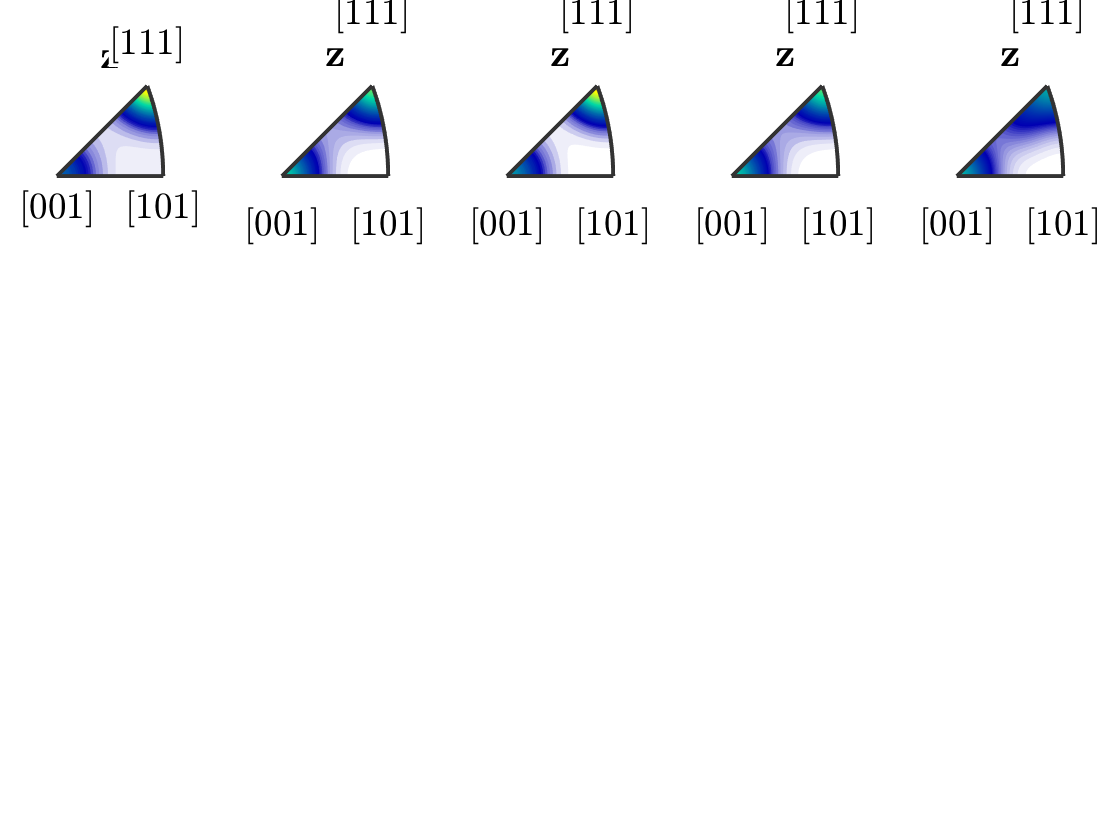

mtexFig = newMtexFigure('layout',[1,5]);

for i = 1:5
    presentODF = odf{i,1};
    plotIPDF(presentODF,zvector)
    clim([0,8]);
    nextAxis
end 

## Compression

If we wanted to, we could do all of the compression in a second exterior loop above, but I'll just copy and paste the code instead. 

compression = vpscDeformation; 
compression.fromfile('COMPRES_extrusion.3')

odf = cell(5,1);
for ii = 1:5
    run = vpscRun(parameters);
    run.parameters.interactionType(1) = ii-1; % this is all that's required to change the interaction type! 
    run.single_crystal{1} = fccSX;
    run.magic_vpsc_box_path = magicPath; 
    run.texture_in{1} = fccTex;
    run.processes{1} = compression;
    run.output_path = ['OutFolderCompression\Interaction_' num2str(ii-1)]; 
    run.write_inputs_to_magic_vpsc_box;
    run.call_VPSC_executable;
    run.store_run_data;

    texOut = fullfile(run.output_path,'TEX_PH1.OUT');
    odf{ii,1} = SO3Fun.load(texOut,'CS',CS,'SS',SS,'density','resolution',5*degree,...
        'interface','generic', 'ColumnNames', { 'phi1' 'Phi' 'phi2' 'Weight'}, 'Bunge');
end 

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   2      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   3      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   4      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   5      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   6      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   7      *** FULL CONSTRAINT CALCULATION         
   ITSGR    SIGGR      SIGAV        DAV 
 
 
*******   STEP   8      

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
   10  0.993E-04  0.151E-04  0.407E-04 
 
 
*******   STEP   2      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    4  0.842E-03  0.118E-03  0.499E-03 
 
 
*******   STEP   3      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    4  0.591E-03  0.806E-04  0.246E-03 
 
 
*******   STEP   4      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    4  0.574E-03  0.999E-04  0.589E-03 
 
 
*******   STEP   5      *** AFFINE CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    4  0.586E-03  0.132E-03  0.903E-03 
 
 
*******   STEP   6      *** AFFINE CALCULATI

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    7  0.143E-03  0.885E-03  0.102E-03 
 
 
*******   STEP   2      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.654E-03  0.887E-03  0.478E-03 
 
 
*******   STEP   3      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.280E-03  0.958E-03  0.651E-03 
 
 
*******   STEP   4      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.220E-03  0.733E-03  0.294E-03 
 
 
*******   STEP   5      *** SECANT CALCULATION                  
   ITSGR    SIGGR      SIGAV        DAV 
    2  0.281E-03  0.665E-03  0.137E-03 
 
 
*******   STEP   6      *** SECANT CALCULATI

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
   10  0.927E-04  0.390E-03  0.650E-03 
 
 
*******   STEP   2      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    6  0.125E-03  0.579E-03  0.176E-03 
 
 
*******   STEP   3      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    6  0.147E-03  0.666E-03  0.265E-03 
 
 
*******   STEP   4      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.102E-03  0.982E-03  0.557E-03 
 
 
*******   STEP   5      *** N_EFF=cte CALCULATION               
   ITSGR    SIGGR      SIGAV        DAV 
    5  0.119E-03  0.911E-03  0.543E-03 
 
 
*******   STEP   6      *** N_EFF=cte CALCUL

 *************************************************** 
 SINGLE ELEMENT CALCULATION 
 SINGLE PHASE CALCULATION 
 *************************************************** 
 --> TOTAL NUMBER OF GRAINS IS   500 
 
 
*******   STEP   1      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
   16  0.474E-04  0.821E-03  0.350E-03 
 
 
*******   STEP   2      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.143E-03  0.690E-03  0.665E-04 
 
 
*******   STEP   3      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.474E-04  0.755E-03  0.358E-03 
 
 
*******   STEP   4      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.131E-03  0.665E-03  0.172E-03 
 
 
*******   STEP   5      *** TANGENT CALCULATION                 
   ITSGR    SIGGR      SIGAV        DAV 
    9  0.125E-03  0.607E-03  0.601E-04 
 
 
*******   STEP   6      *** TANGENT CALCULAT

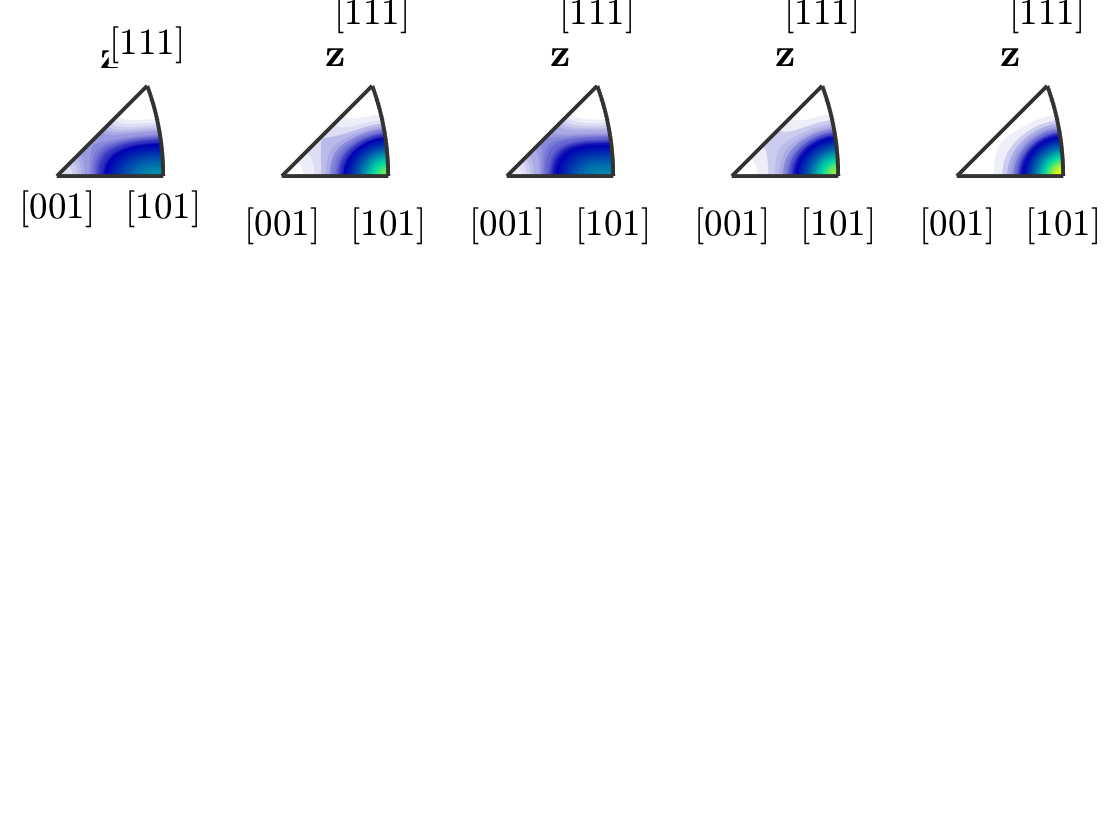


mtexFig = newMtexFigure('layout',[1,5]);

for i = 1:5
    presentODF = odf{i,1};
    plotIPDF(presentODF,zvector)
    clim([0,8]);
    nextAxis
end 